# SpineLeaf

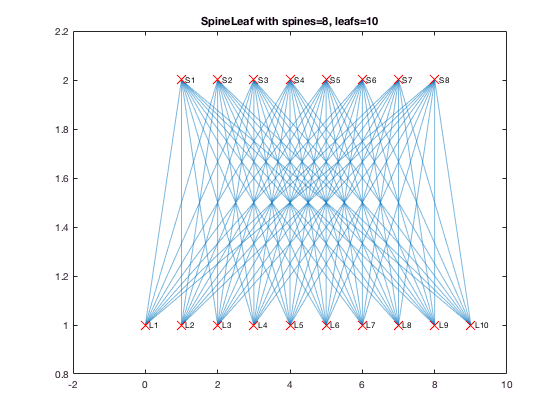

N=10;%Number of disjoint links to compute
topology='SpineLeaf';
spines=8;
leafs=10;
source='L1';
dest='L3';

G=graphTopology(false,false,topology,spines,leafs);
tit= sprintf('%s with spines=%d, leafs=%d',topology,spines, leafs);
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
title(tit);
print(fig,[tit '.png'],'-dpng');

## Known topology

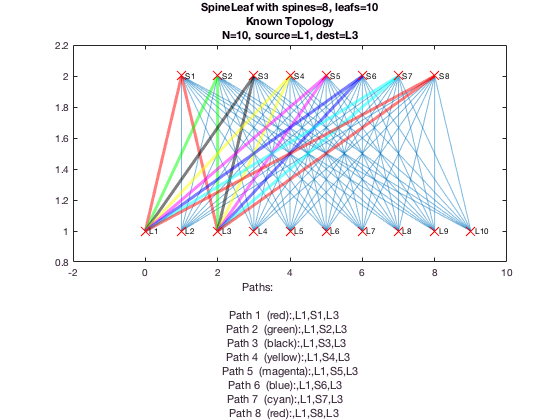

%Known topology
sour=findnode(G,source);
des=findnode(G,dest);
paths=disjoint( topology, 'edges', sour, des, N, false, spines, leafs);
ordest=sprintf('N=%d, source=%s, dest=%s',N,source,dest);
tit1=[tit,'-known topology'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
plotPaths(p, paths);
title({tit;'Known Topology';ordest});
xlabel(stringPaths(paths,G));
print(fig,[tit1 '.png'],'-dpng');

## Known topology and nodes that can't be used

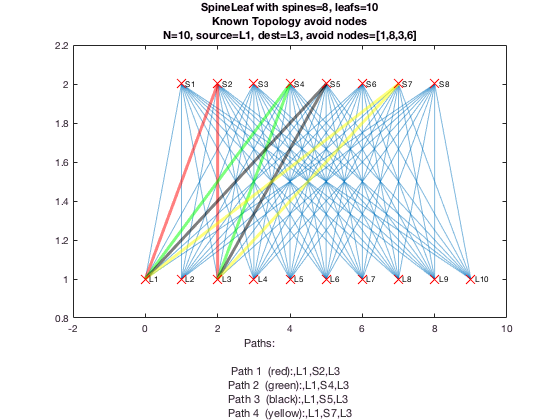

%Known topology and nodes that can't be used
sour=findnode(G,source);
des=findnode(G,dest);
paths=disjoint( topology, 'edges', sour, des, N, false, spines, leafs, [1,8,3,6]);
ordest=sprintf('N=%d, source=%s, dest=%s, avoid nodes=[1,8,3,6]',N,source,dest);
tit1=[tit,'-known topology nodes not'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
plotPaths(p, paths);
title({tit;'Known Topology avoid nodes';ordest});
xlabel(stringPaths(paths,G));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology edge disjoint normal 

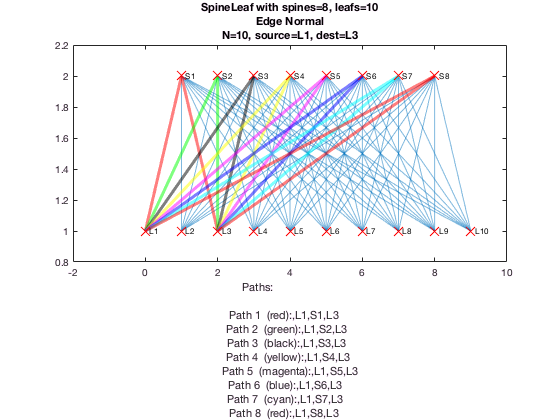

paths=disjoint('other', 'edges', source, dest, N, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 1, true);

## Unknown topology edge disjoint max 

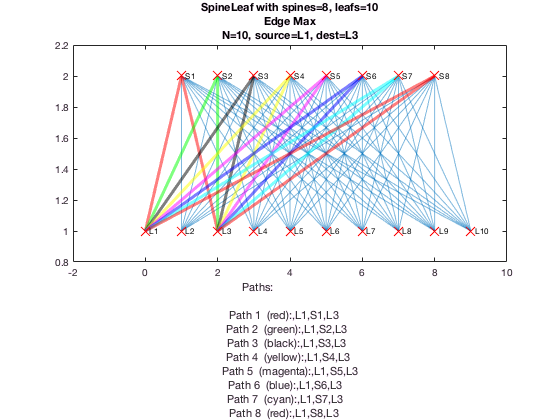

paths=disjoint( 'other', 'edges', source, dest, N, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 2, true);

## Unknown topology node disjoint normal 

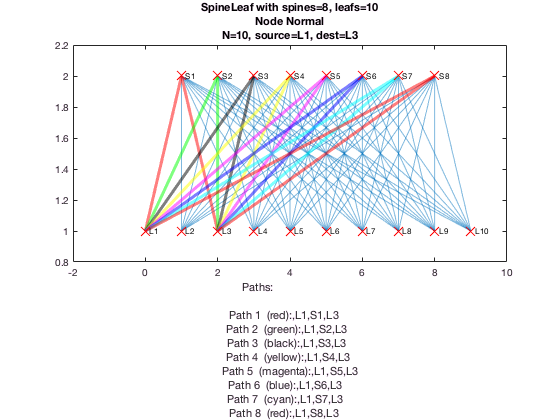

paths=disjoint( 'other', 'nodes', source, dest, N, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 3, true);

## Unknown topology node disjoint max

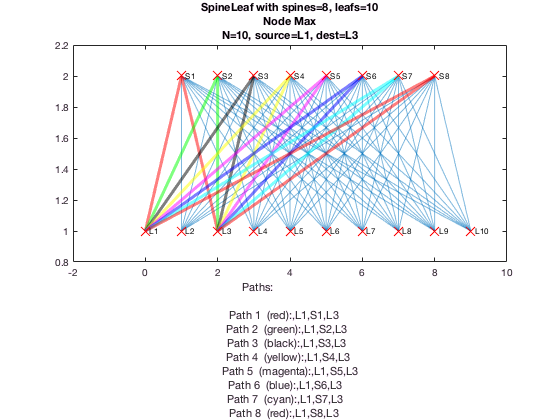

paths=disjoint( 'other', 'nodes', source, dest, N, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 4, true);

# VL2

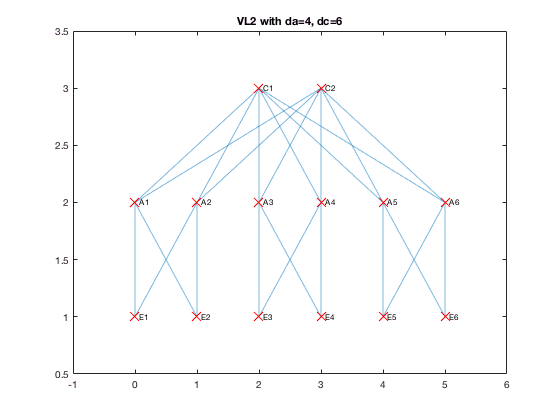

N=10;%Number of disjoint links to compute
topology='VL2';
da=4;
dc=6;
source='E1';
dest='E5';

G=graphTopology(false,false,topology,dc,da);
tit= sprintf('%s with da=%d, dc=%d',topology,da, dc);
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
title(tit);
print(fig,[tit '.png'],'-dpng');

## Known topology

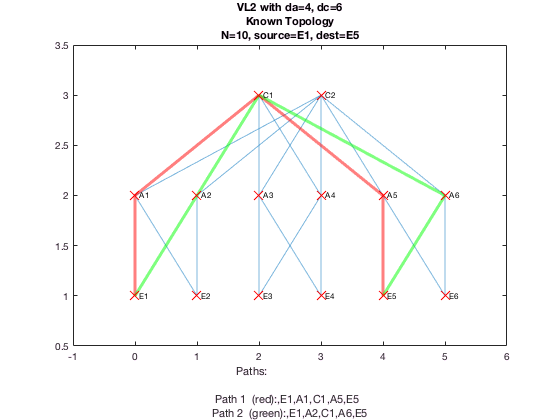

%Known topology
sour=findnode(G,source);
des=findnode(G,dest);
paths=disjoint( topology, 'edges', sour, des, N, false, dc,da);
ordest=sprintf('N=%d, source=%s, dest=%s',N,source,dest);
tit1=[tit,'-known topology'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
plotPaths(p, paths);
title({tit;'Known Topology';ordest});
xlabel(stringPaths(paths,G));
print(fig,[tit1 '.png'],'-dpng');

## Known topology and nodes that can't be used

%Known topology and nodes that can't be used
sour=findnode(G,source);
des=findnode(G,dest);
tic
paths=disjoint( topology, 'edges', sour, des, N, false, dc, da, [1,8,3,6]); toc;

Elapsed time is 0.085556 seconds.


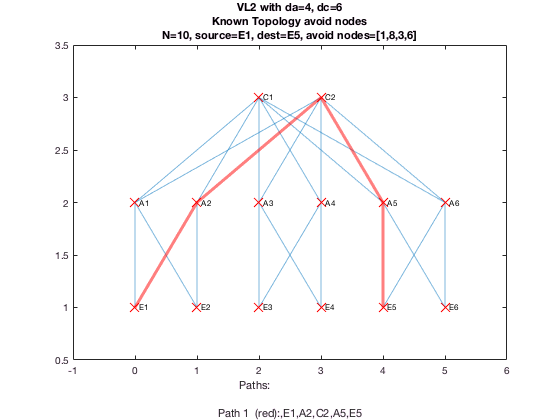

ordest=sprintf('N=%d, source=%s, dest=%s, avoid nodes=[1,8,3,6]',N,source,dest);
tit1=[tit,'-known topology nodes not'];
fig=figure('Name',tit1,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
plotPaths(p, paths);
title({tit;'Known Topology avoid nodes';ordest});
xlabel(stringPaths(paths,G));
print(fig,[tit1 '.png'],'-dpng');

## Unknown topology edge disjoint normal 

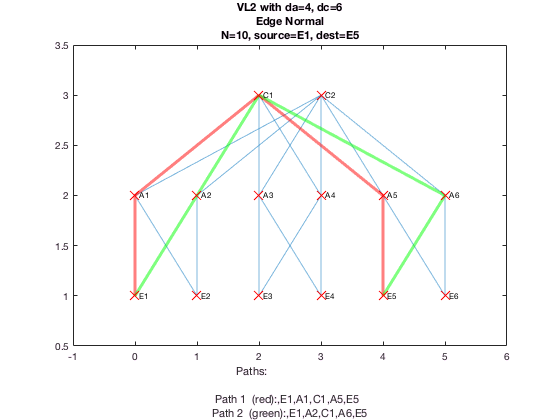

paths=disjoint('other', 'edges', source, dest, N, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 1, true);

## Unknown topology edge disjoint max

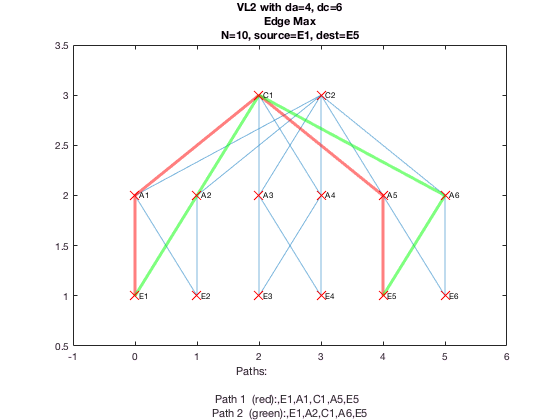

paths=disjoint( 'other', 'edges', source, dest, N, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 2, true);

## Unknown topology node disjoint normal 

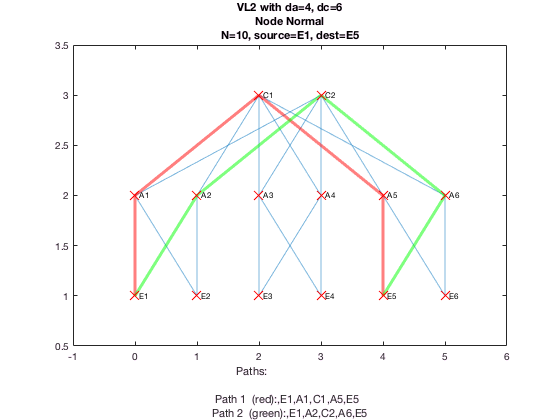

paths=disjoint( 'other', 'nodes', source, dest, 8, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 3, true);

## Unknown topology node disjoint max

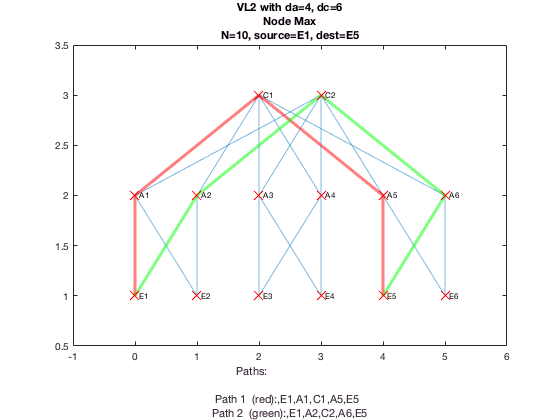

paths=disjoint( 'other', 'nodes', source, dest, 8, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 4, true);

# Portland

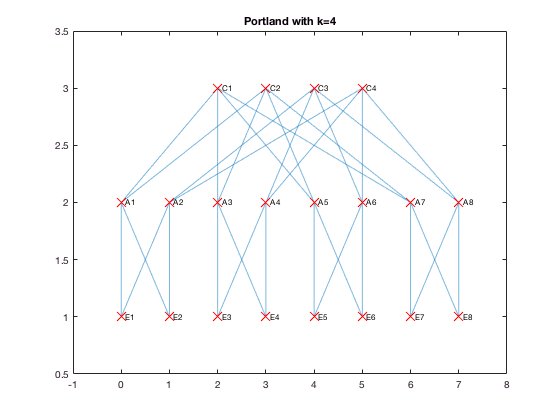

N=10;%Number of disjoint links to compute
topology='Portland';
k=4;
source='E1';
dest='E7';

G=graphTopology(false,false,topology,k);
tit= sprintf('%s with k=%d',topology,k);
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
title(tit);
print(fig,[tit '.png'],'-dpng');

## Unknown topology edge disjoint normal 

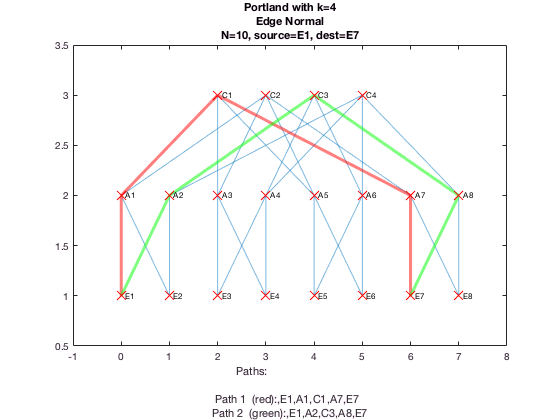

paths=disjoint('other', 'edges', source, dest, N, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 1, true);

## Unknown topology edge disjoint max 

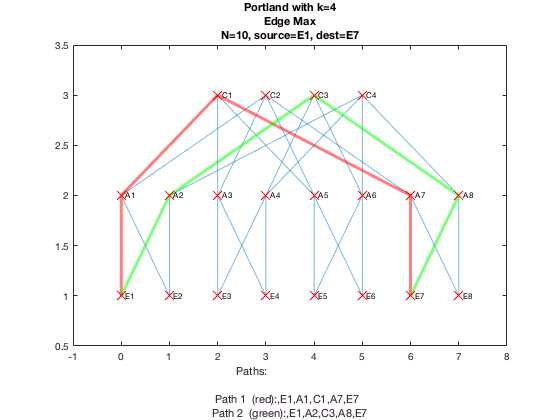

paths=disjoint( 'other', 'edges', source, dest, N, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 2, true);

## Unknown topology node disjoint normal 

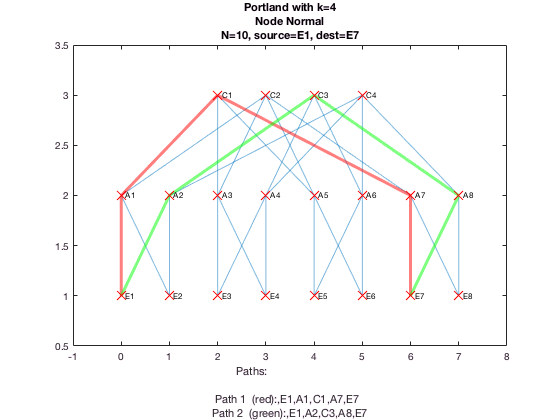

paths=disjoint( 'other', 'nodes', source, dest, 8, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 3, true);

## Unknown topology node disjoint max

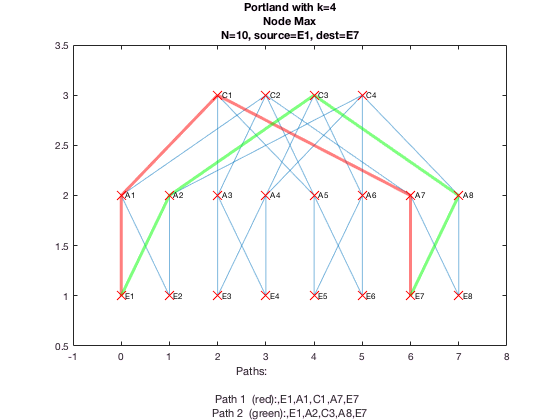

paths=disjoint( 'other', 'nodes', source, dest, 8, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 4, true);

# Altoona Facebook

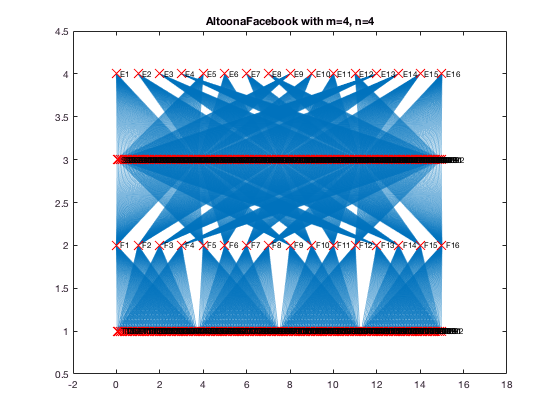

N=10;%Number of disjoint links to compute
topology='AltoonaFacebook';
m=4;
n=4;
source='T1';
dest='T100';

G=graphTopology(false,false,topology,m,n);
tit= sprintf('%s with m=%d, n=%d',topology,m, n);
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G);
title(tit);
print(fig,[tit '.pdf'],'-dpdf');

## Unknown topology edge disjoint normal 

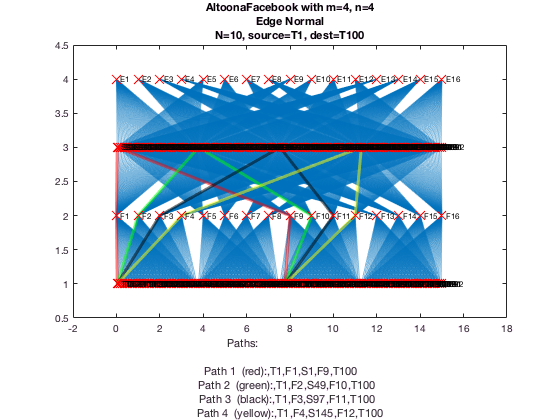

paths=disjoint('other', 'edges', source, dest, N, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 1, true);

## Unknown topology edge disjoint max 

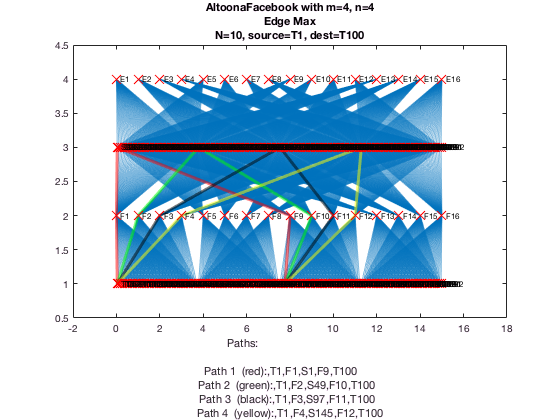

paths=disjoint( 'other', 'edges', source, dest, N, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 2, true);

## Unknown topology node disjoint normal 

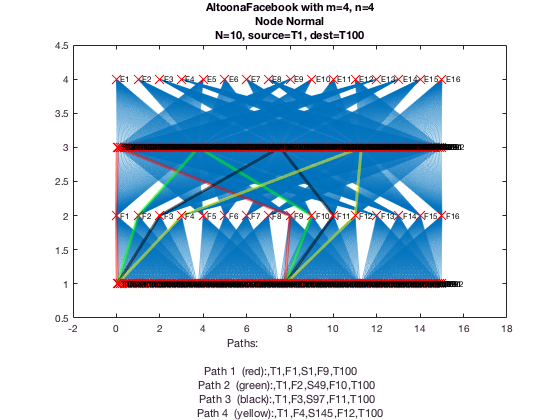

paths=disjoint( 'other', 'nodes', source, dest, 8, G, false, false);
printPngPaths(N,source,dest,tit,G,paths, 3, true);

## Unknown topology node disjoint max

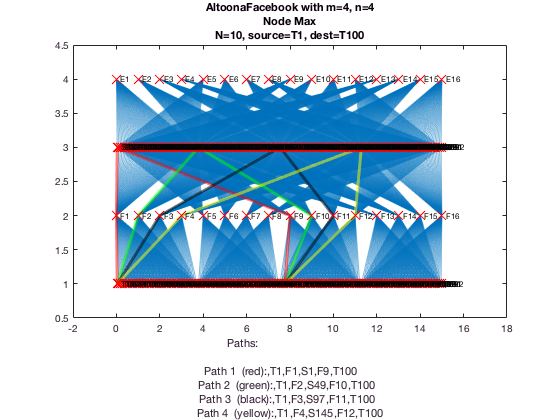

paths=disjoint( 'other', 'nodes', source, dest, 8, G, false, true);
printPngPaths(N,source,dest,tit,G,paths, 4, true);

# BYHAND topology1

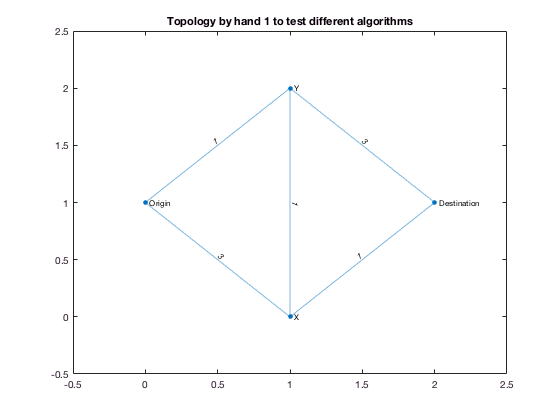

nnodes=4;
N=3;
source=1;
dest=4;
% Nodes Table
endnodes = cell(nnodes, 1);
Xpoint(nnodes,1)=1;
Ypoint(nnodes,1)=1;
endnodes{1}='Origin';
Xpoint(1,1)=0;
Ypoint(1,1)=1;
endnodes{2}='Y';
Xpoint(2,1)=1;
Ypoint(2,1)=2;
endnodes{3}='X';
Xpoint(3,1)=1;
Ypoint(3,1)=0;
endnodes{4}='Destination';
Xpoint(4,1)=2;
Ypoint(4,1)=1;
nodestable = table(endnodes,Xpoint,Ypoint,'VariableNames',{'Name';'Xpoint';'Ypoint'});

NetCostMatrix=[0 1 3 0; 1 0 1 3; 3 1 0 1; 0 3 1 0];

edgetable = edgeTableCostMatrix(NetCostMatrix);
G=graph(edgetable,nodestable);
tit= sprintf('Topology by hand 1 to test different algorithms');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p=plotGraphtopology(G,'EdgeLabel', G.Edges.Weight);
title(tit);
print(fig,[tit '.png'],'-dpng');

## Unknown topology edge disjoint normal 

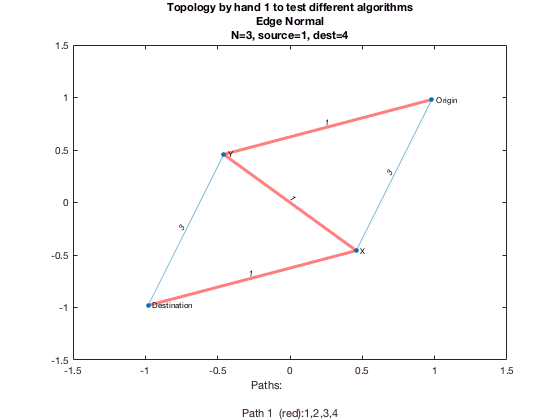

paths=disjoint('other', 'edges', source, dest, N, NetCostMatrix, true, false);
printPngPaths(N,source,dest,tit,G,paths, 1, false,'EdgeLabel', G.Edges.Weight);

## Unknown topology edge disjoint max 

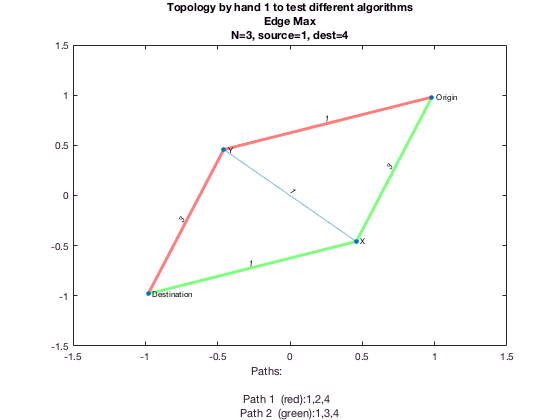

paths=disjoint( 'other', 'edges', source, dest, N, NetCostMatrix, true, true);
printPngPaths(N,source,dest,tit,G,paths, 2, false,'EdgeLabel', G.Edges.Weight);

## Unknown topology node disjoint normal 

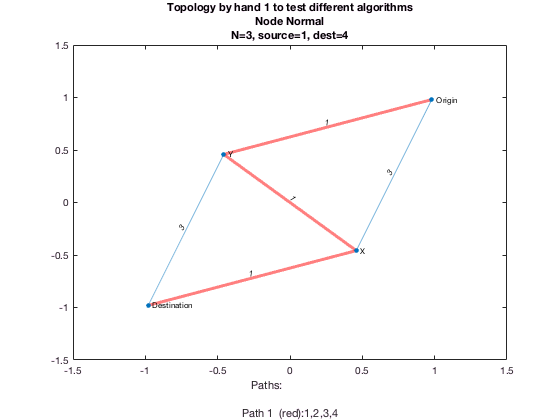

paths=disjoint( 'other', 'nodes', source, dest, 8, NetCostMatrix, true, false);
printPngPaths(N,source,dest,tit,G,paths, 3, false,'EdgeLabel', G.Edges.Weight);

## Unknown topology node disjoint max

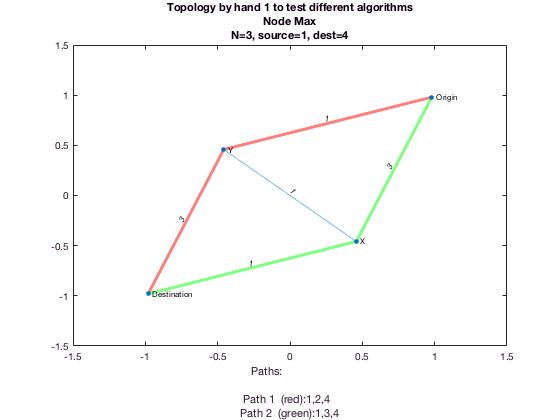

paths=disjoint( 'other', 'nodes', source, dest, 8, NetCostMatrix, true, true);
printPngPaths(N,source,dest,tit,G,paths, 4, false,'EdgeLabel', G.Edges.Weight);

# BYHAND topology2

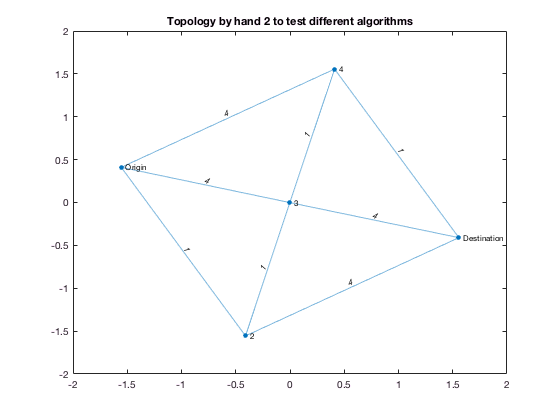

nnodes=5;
N=4;
source=1;
dest=5;
% Nodes Table
endnodes = cell(nnodes, 1);
Xpoint(nnodes,1)=1;
Ypoint(nnodes,1)=1;
endnodes{1}='Origin';
endnodes{2}='2';
endnodes{3}='3';
endnodes{4}='4';
endnodes{5}='Destination';
nodestable = table(endnodes,'VariableNames',{'Name'});

NetCostMatrix=[0 1 4 4 0; 1 0 1 0 4; 4 1 0 1 4; 4 0 1 0 1 ; 0 4 4 1 0];

edgetable = edgeTableCostMatrix(NetCostMatrix);
G=graph(edgetable,nodestable);
tit= sprintf('Topology by hand 2 to test different algorithms');
fig=figure('Name',tit,'NumberTitle','off');
clf(fig);
p = plot(G,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
title(tit);
print(fig,[tit '.png'],'-dpng');

## Unknown topology edge disjoint normal 

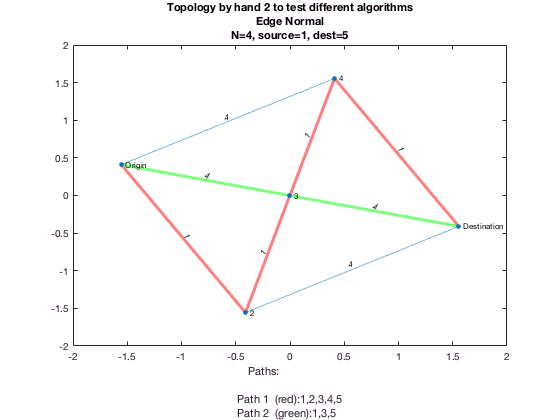

paths=disjoint('other', 'edges', source, dest, N, NetCostMatrix, true, false);
printPngPaths(N,source,dest,tit,G,paths, 1, false,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);

## Unknown topology edge disjoint max 

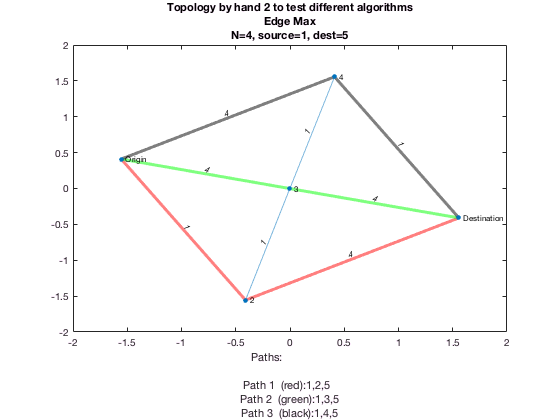

paths=disjoint( 'other', 'edges', source, dest, N, NetCostMatrix, true, true);
printPngPaths(N,source,dest,tit,G,paths, 2, false,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);

## Unknown topology node disjoint normal 

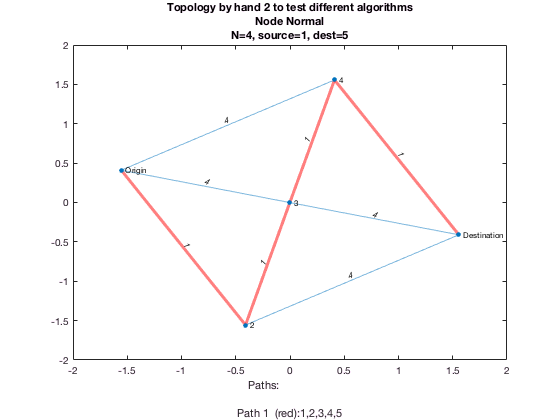

paths=disjoint( 'other', 'nodes', source, dest, 8, NetCostMatrix, true, false);
printPngPaths(N,source,dest,tit,G,paths, 3, false,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);

## Unknown topology node disjoint max

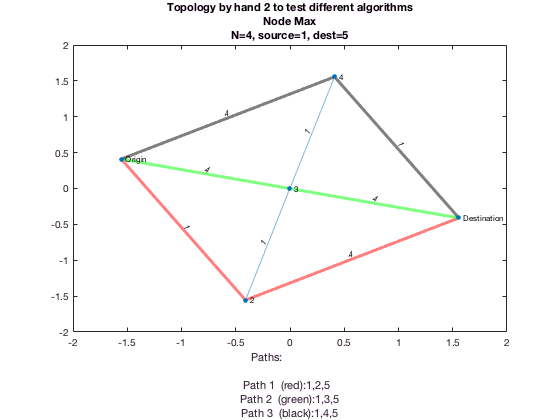

paths=disjoint( 'other', 'nodes', source, dest, 8, NetCostMatrix, true, true);
printPngPaths(N,source,dest,tit,G,paths, 4, false,'NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);